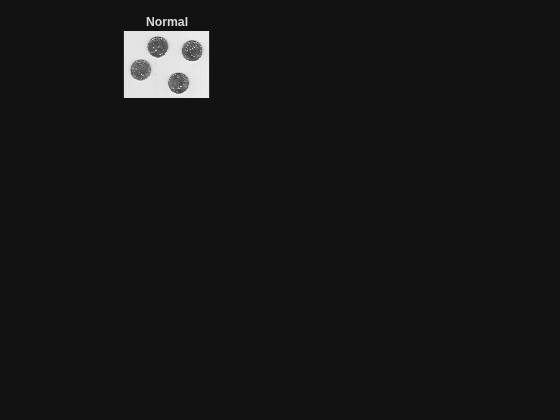

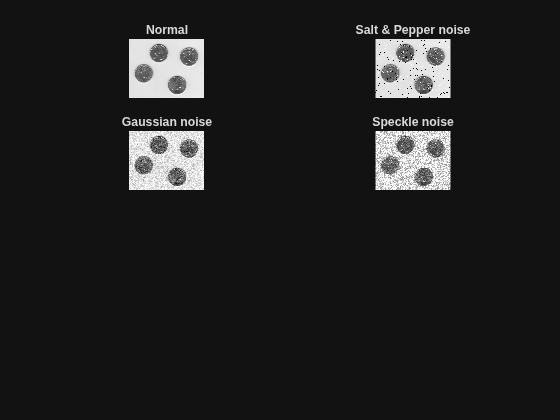

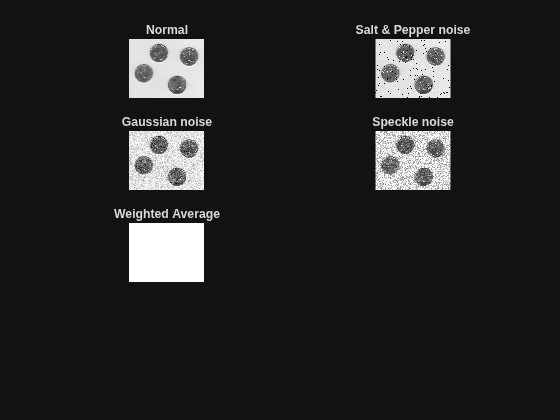

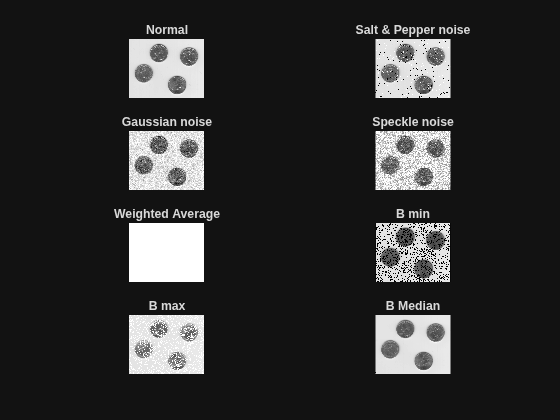

clc;

clear all;
close all;

% step1: read image
a = imread('eight.tif');
subplot(4,2,1);
imshow(a);
title('Normal');

% step2: add different types of noise

b = imnoise(a, "salt & pepper");
subplot(4,2,2);
imshow(b);
title('Salt & Pepper noise');
c = imnoise(a, "gaussian");
subplot(4,2,3);
imshow(c);
title('Gaussian noise');
d = imnoise(a, "speckle");
subplot(4,2,4);
imshow(d);
title('Speckle noise');

h1 = (1/9)*ones(3,3);
h2=(1/25)*ones(5,5);
hw=[1 2 1; 2 4 2; 1 2 1];
hw = hw/ sum(hw(:));
bw = conv2(double(b),hw, 'same');
subplot(4,2,5);
imshow(bw);
title('Weighted Average');



bmin = ordfilt2(b,1,ones(3,3));
bmax = ordfilt2(b,9,ones(3,3));
bmed = ordfilt2(b,5,ones(3,3));
subplot(4,2,6);
imshow(bmin);
title('B min');
subplot(4,2,7);
imshow(bmax);
title('B max');
subplot(4,2,8);
imshow(bmed);
title('B Median');